# 3D Graphics

## Surface Plots

To plot a function of two variables $z = f(x, y)$ we use the command `meshgrid` to construct a rectangular grid on which to evaluate the function. Notice the structure of the matrices. The rows of `X` are copies of the vector `x` and the columns of `Y` are copies of the vector `y`.

x = -1:0.5:1;
y = -1:0.5:1;
[X, Y] = meshgrid(x,y)

X =    -1.0000   -0.5000         0    0.5000    1.0000
   -1.0000   -0.5000         0    0.5000    1.0000
   -1.0000   -0.5000         0    0.5000    1.0000
   -1.0000   -0.5000         0    0.5000    1.0000
   -1.0000   -0.5000         0    0.5000    1.0000


Y =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000
         0         0         0         0         0
    0.5000    0.5000    0.5000    0.5000    0.5000
    1.0000    1.0000    1.0000    1.0000    1.0000


Compute the matrix of function values Z and draw the surface with `surf`.

Z = sqrt(X.^2 + Y.^2)

Z =     1.4142    1.1180    1.0000    1.1180    1.4142
    1.1180    0.7071    0.5000    0.7071    1.1180
    1.0000    0.5000         0    0.5000    1.0000
    1.1180    0.7071    0.5000    0.7071    1.1180
    1.4142    1.1180    1.0000    1.1180    1.4142


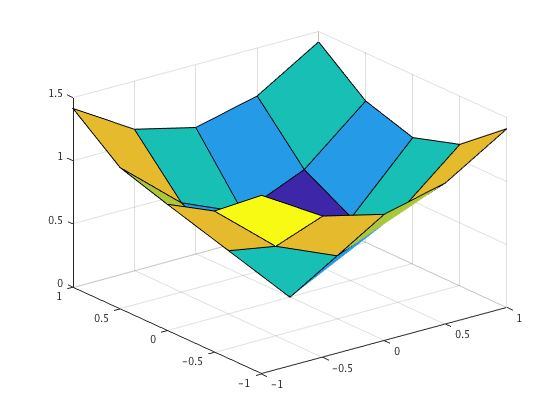

surf(X, Y, Z)

Another possibility is to use the command `mesh`.

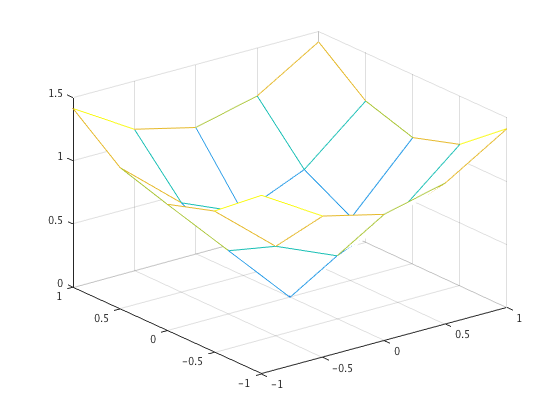

mesh(X, Y, Z)

We can also call `meshgrid` with one vector argument, which is then used in both x and y directions. The surface has plenty of attributes. Here we change the colouring of the surface.

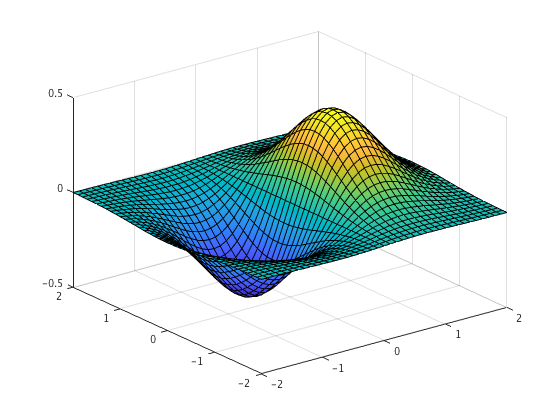

[X, Y] = meshgrid(-2:0.1:2);
Z = X.*exp(-X.^2 - Y.^2);
surf(X, Y, Z, 'FaceColor', 'interp')

An equivalent way to do the same as above.

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [41×41 double]
           YData: [41×41 double]
           ZData: [41×41 double]
           CData: [41×41 double]

  Show all properties


h = surf(X, Y, Z);
h.FaceColor = 'interp'

Sets shading to interpolated and also removes the mesh lines.

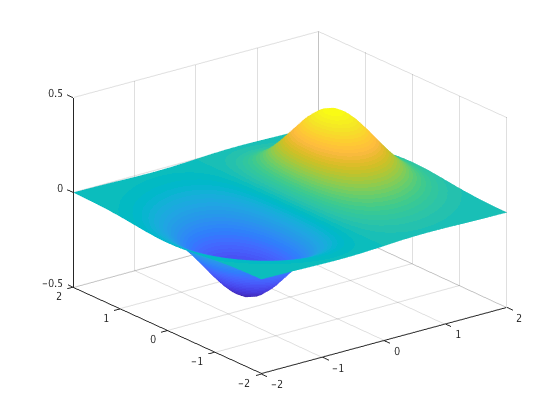

surf(X, Y, Z);
shading interp

We can also set shading to flat

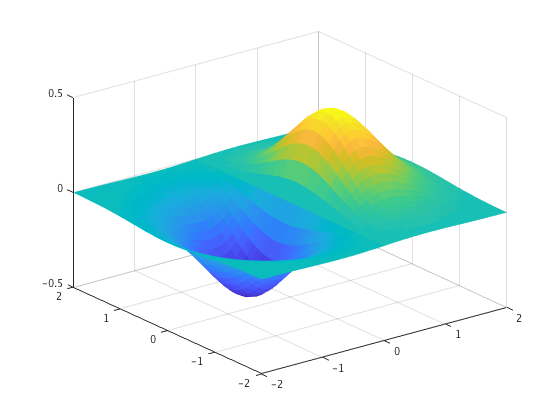

shading flat

or faceted, which is the default.

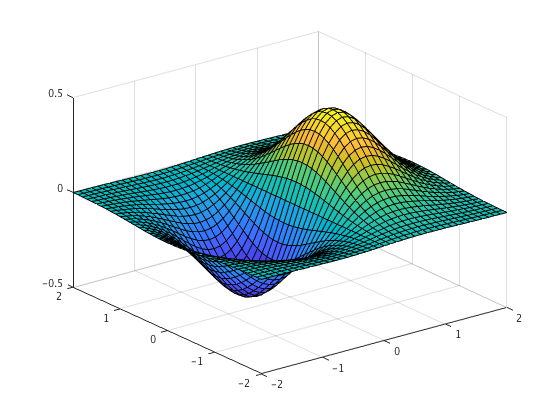

shading faceted

Meshlines only in the x direction

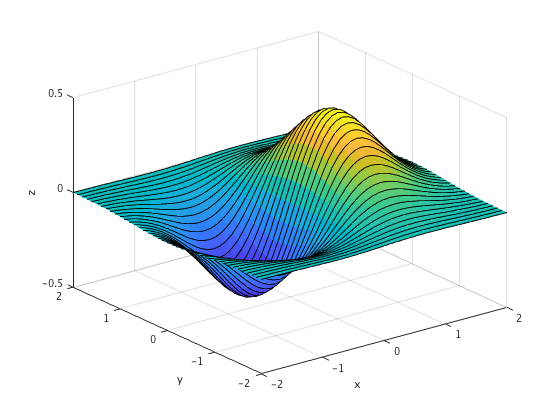

h = surf(X, Y, Z, 'MeshStyle', 'row');
xlabel('x'); ylabel('y'); zlabel('z')

Only in the y direction

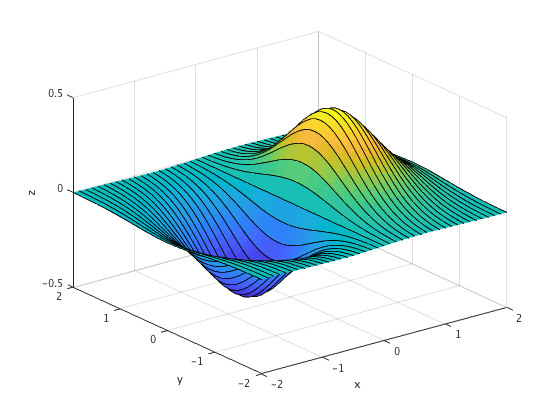

set(h, 'MeshStyle', 'col');

Both directions, the default.

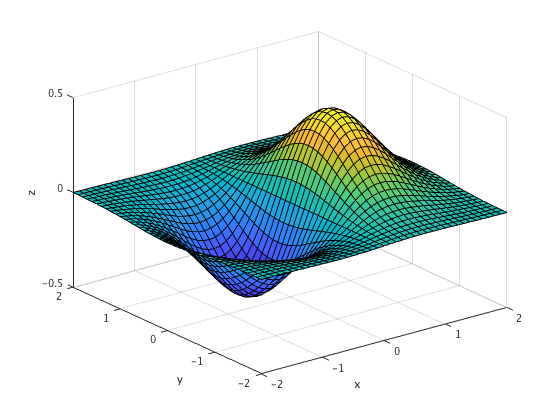

set(h, 'MeshStyle', 'both');

The command `help graph3d` lists all the 3d graphics commands.

help graph3d

  Three dimensional graphs.
  
  Elementary 3-D plots.
    plot3      - Plot lines and points in 3-D space.
    mesh       - 3-D mesh surface.
    surf       - 3-D colored surface.
    fill3      - Filled 3-D polygons.
   
  Color control.
    colormap   - Color look-up table.
    caxis      - Pseudocolor axis scaling.
    shading    - Color shading mode.
    hidden     - Mesh hidden line removal mode.
    brighten   - Brighten or darken color map.
    colordef   - Set color defaults.
    graymon    - Set graphics defaults for gray-scale monitors.
    cmpermute  - Rearrange colors in colormap.

## Parametric plot

We plot a sphere using the spherical coordinates $\theta$ and $\phi$.

First form a meshgrid of the parameter domain $[0, \pi] \times [0, 2\pi]$.

theta = linspace(0, pi, 40);
phi = linspace(0, 2*pi, 20);
[T, P] = meshgrid(theta, phi);

Next compute the $x$, $y$, and $z$ coordinates from the parametrization and plot the surface.

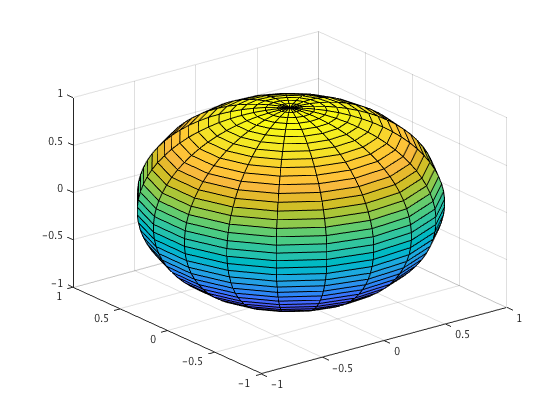

X = sin(T).*cos(P);
Y = sin(T).*sin(P);
Z = cos(T);
surf(X, Y, Z)

The colouring of the surface may be defined for example by a function of `T` and `P`. Here `C` gives the color for each `Z` value, so it has to be the same size as `Z` . The default is to use `Z` as `C`. The `C` values are stored as the `CData` property of the plot object.

C = sin(T*2) + cos(P);
surf(X, Y, Z, C)
axis equal

This freezes the axis ratio so we can rotate the 3D object without stretch-to-fill (try it).

axis vis3d

## Colormap

The colormap is used to map the vertex `C` values into colors. Let us plot a pointy hat.

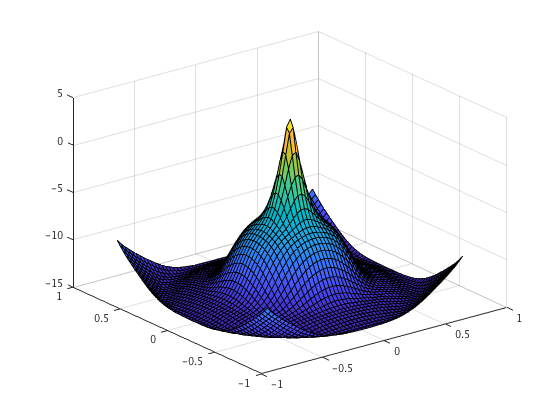

[Xf, Yf] = meshgrid(-0.8:0.03:0.8);
Rf = sqrt(Xf .^ 2 + Yf .^ 2);
Zf = -20.18*sin(2*Rf) - 1.59*sin(4*Rf) - 1.06*sin(6*Rf) - 0.795*sin(8*Rf) -...
	0.637*sin(10*Rf) - 0.53*sin(12*Rf) - 0.455*sin(14*Rf) - 0.398*sin(16*Rf) -...
	0.354*sin(18*Rf) + 5;
hf = surf(Xf, Yf, Zf);

colormap default

The colormap is chosen with the `colormap` command. The command `colorbar` adds a colorbar to the figure.

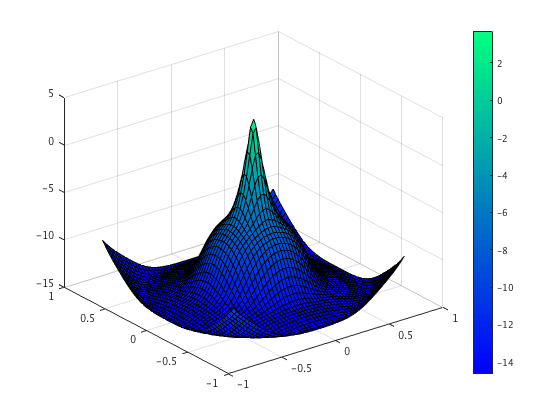

colormap winter
colorbar

Here are all the predefined colormaps.

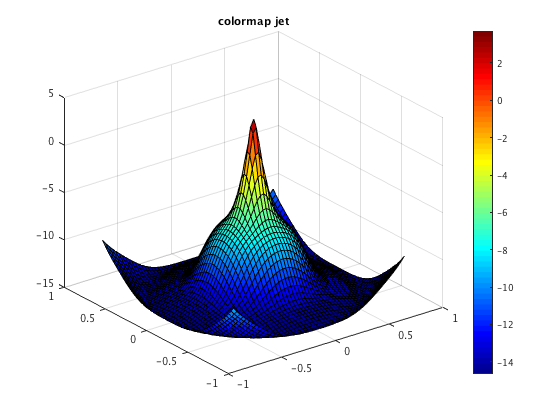

colormap(jet), title('colormap jet')

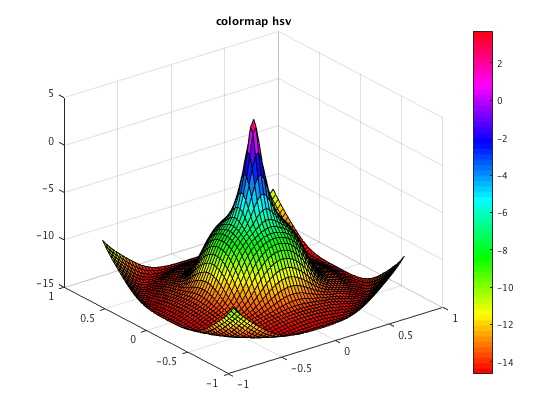

colormap(hsv), title('colormap hsv')

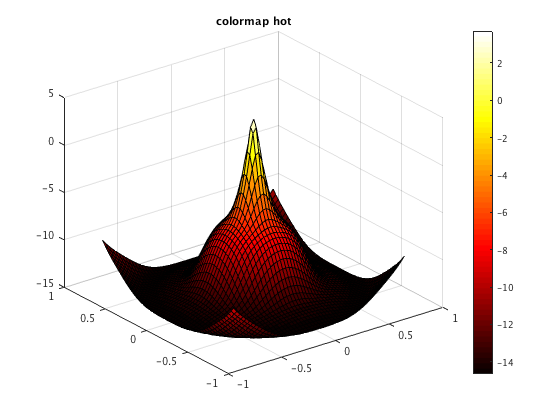

colormap(hot), title('colormap hot')

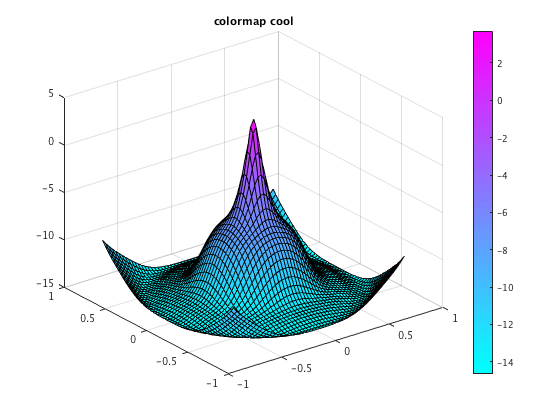

colormap(cool), title('colormap cool')

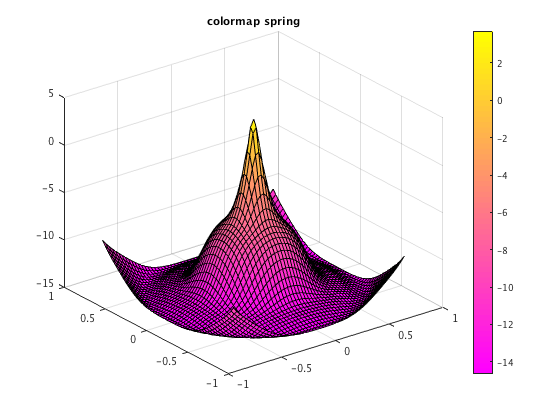

colormap(spring), title('colormap spring')

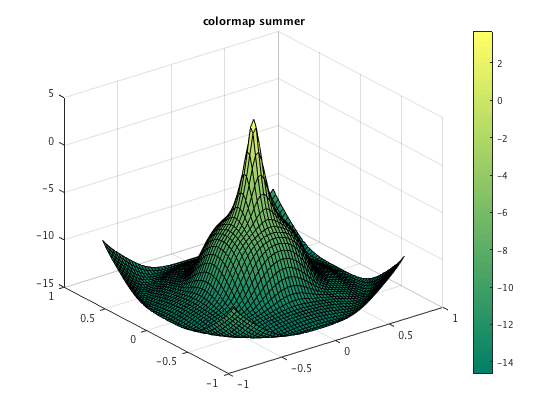

colormap(summer), title('colormap summer')

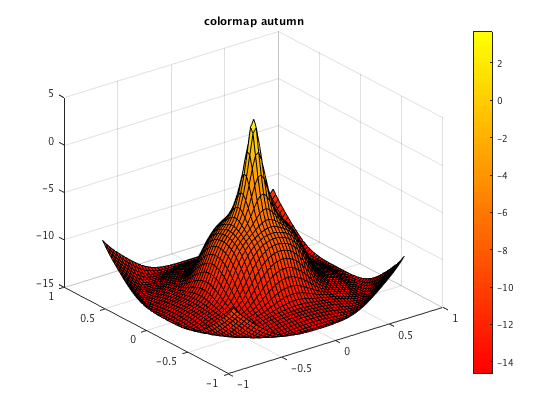

colormap(autumn), title('colormap autumn')

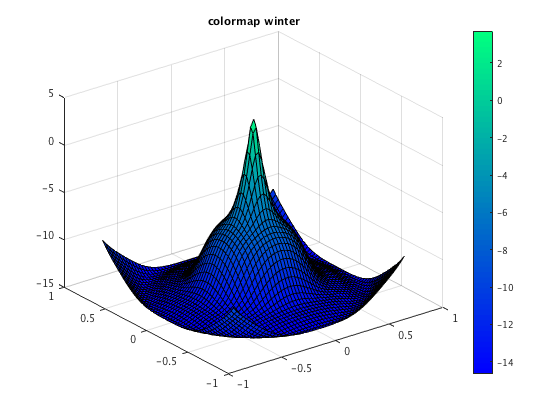

colormap(winter), title('colormap winter')

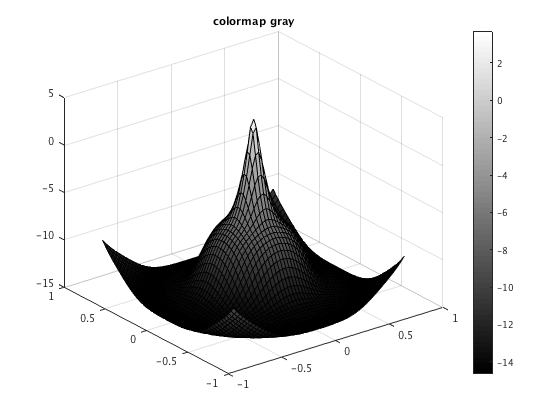

colormap(gray), title('colormap gray')

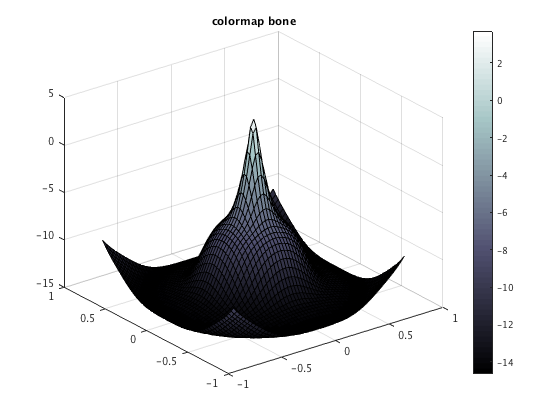

colormap(bone), title('colormap bone')

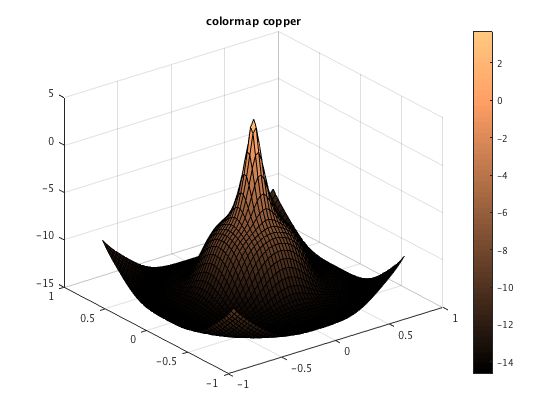

colormap(copper), title('colormap copper')

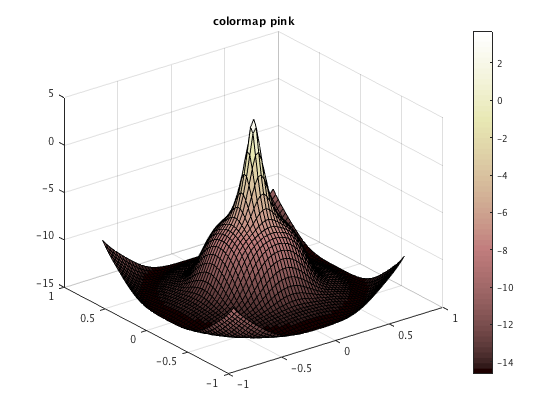

colormap(pink), title('colormap pink')

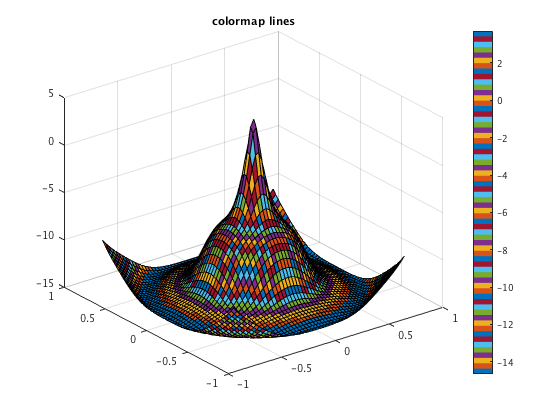

colormap(lines), title('colormap lines')

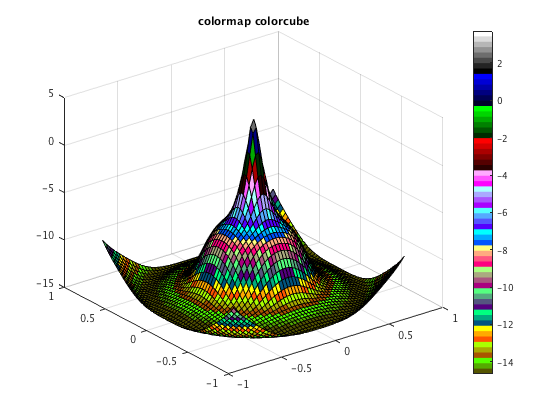

colormap(colorcube), title('colormap colorcube')

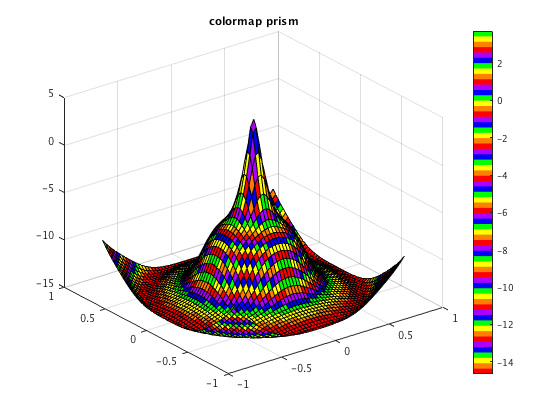

colormap(prism), title('colormap prism')

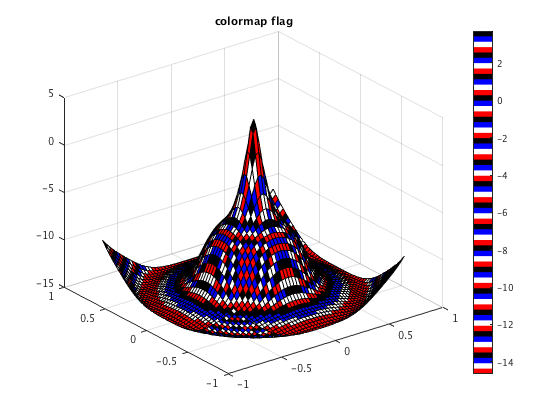

colormap(flag), title('colormap flag')

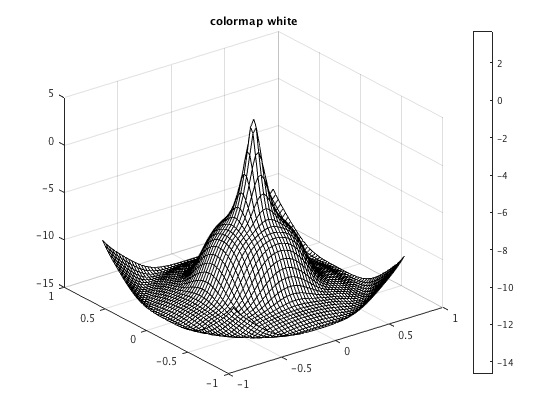

colormap(white), title('colormap white')

The colormap can be any `n x 3` matrix. Here the lower third of the color values `C` are mapped to red, the middle third to green, and the upper third to blue.

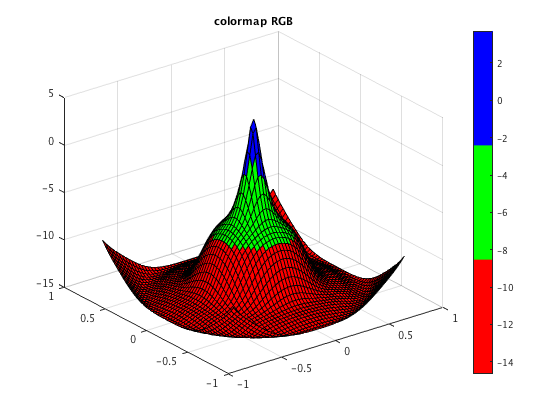

rgb = [1 0 0; 0 1 0; 0 0 1];
colormap(rgb), title('colormap RGB')

Repeating the rgb values gives stripes.

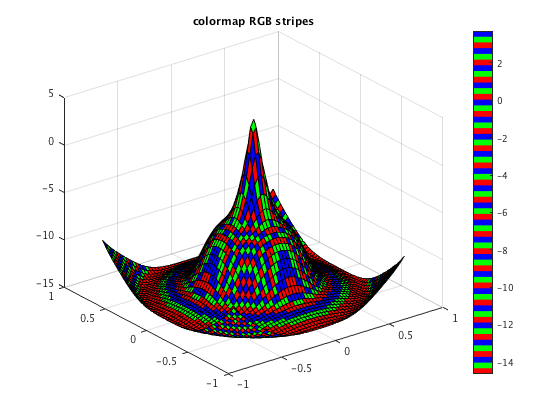

rgbstripes = repmat(rgb, 20, 1);
colormap(rgbstripes), title('colormap RGB stripes')

Back to the default colormap

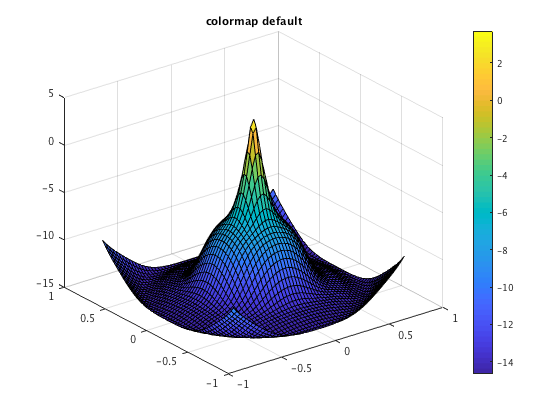

colormap default,  title('colormap default')

Colormaps can also applied to two dimensional images. Let us plot the Mandelbrot set.

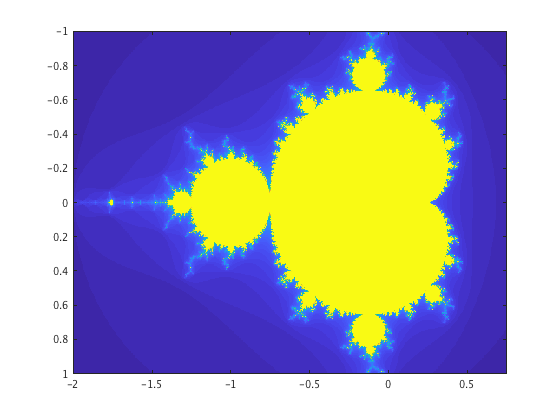

x = linspace(-2, 0.75, 500); y = linspace(-1, 1, 500);
depth = 2000;
K = zeros(length(x), length(y));
Z = zeros(size(K));
[X, Y] = meshgrid(x, y);
C = X + 1i*Y;
for k = 1:depth
    Z = Z.^2 + C;
    K(abs(Z) < 2) = k;
end
image(x, y, K)

Change the colormap

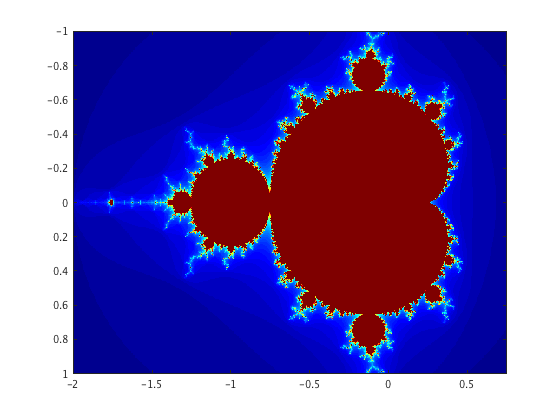

colormap jet

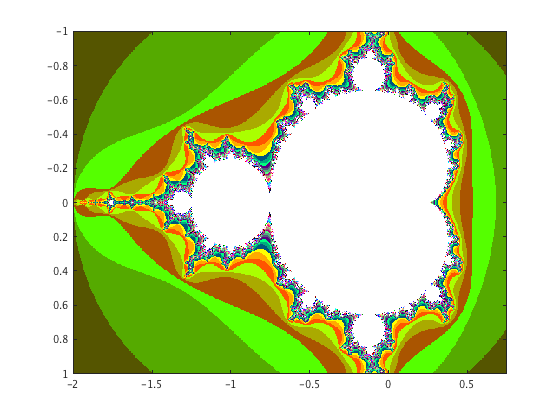

colormap colorcube

colormap default

## Lighting, camera

It is also possible to choose lighting, camera angle, and the surface material for the surface.

Define a surface

[X, Y] = meshgrid(-5:0.1:5);
R = X.^2 + Y.^2;
Z = sin(X.^2 + 3*Y.^2)./(0.1 + R) + 0.5*(X.^2 + 5*Y.^2).*exp(1 - R);

Plot it

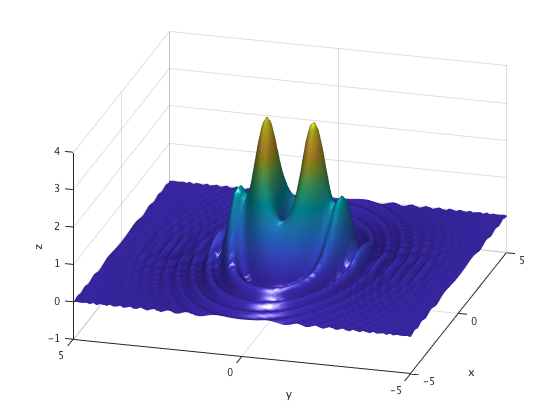

surf(X, Y, Z, 'FaceColor', 'interp', 'EdgeColor','none', 'FaceLighting','gouraud',...
    'AmbientStrength', 0.9, 'DiffuseStrength', 0.9)
lightangle(-70, 60)
material shiny
view([-74, 34])
xlabel('x'), ylabel('y'), zlabel('z')

Some other possibilities

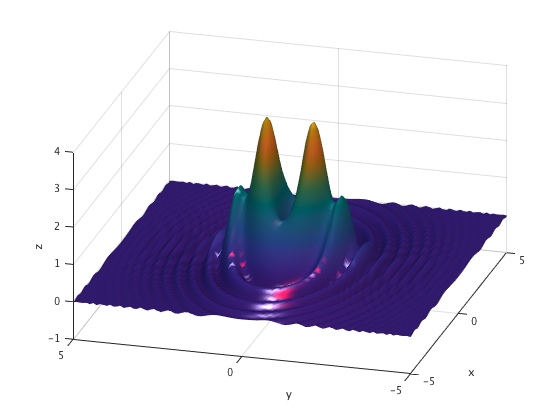

h = light;
h.Position = [-1 -1 0.5];
h.Color = [1 0 0];
material metal

Properties of the light object

set(h)

            BusyAction: {'queue'  'cancel'}
         ButtonDownFcn: {}
              Children: {}
                 Color: {1×0 cell}
             CreateFcn: {}
             DeleteFcn: {}
      HandleVisibility: {'on'  'callback'  'off'}
               HitTest: {'on'  'off'}
         Interruptible: {'on'  'off'}
                Parent: {}
         PickableParts: {'visible'  'none'  'all'}
              Position: {}
              Selected: {'on'  'off'}
    SelectionHighlight: {'on'  'off'}
                 Style: {'infinite'  'local'  'ambient'}
                   Tag: {}
         UIContextMenu: {}
              UserData: {}
               Visible: {'on'  'off'}



Returns the camera angle in a two element vector.

V = get(gca,'view')

V =    -74    34


Set the camera angle.

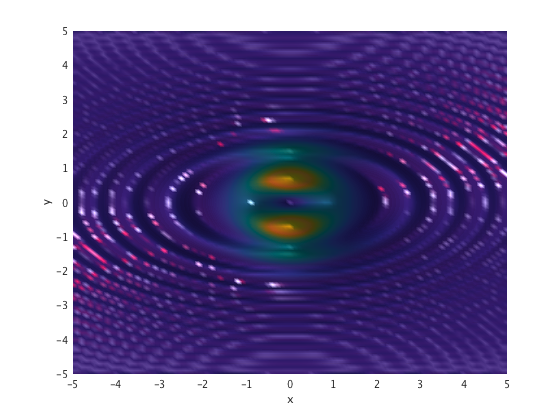

set(gca, 'view', [0 90])

An equivalent way of setting the camera angle.

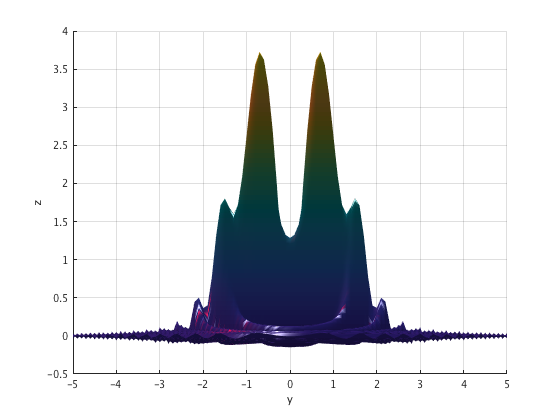

view([90 0])

Sets the default view.

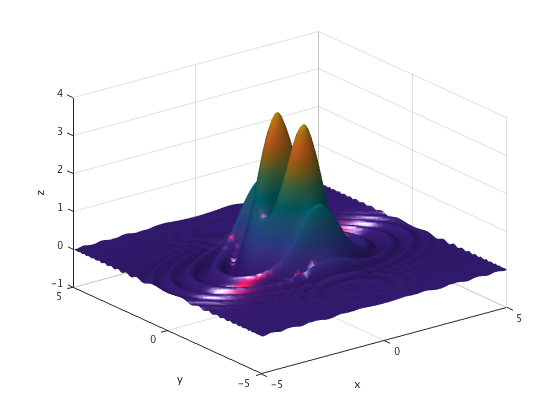

view(3)

We can also rotate the camera around a plot

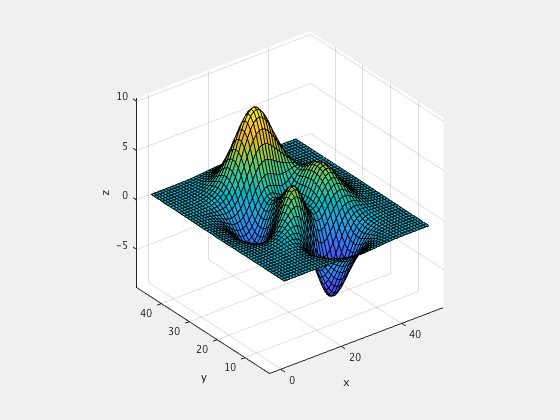

figure('Visible', 'on')
surf(peaks)
xlabel('x'); ylabel('y'); zlabel('z');
axis vis3d
for i=1:360
 camorbit(1, 1)
 drawnow
end

for i=1:360
 camroll(1)
 drawnow
end

## fsurf

The command f`zsurf` is an easy to use surface plotter that takes a function handle as a first argument.

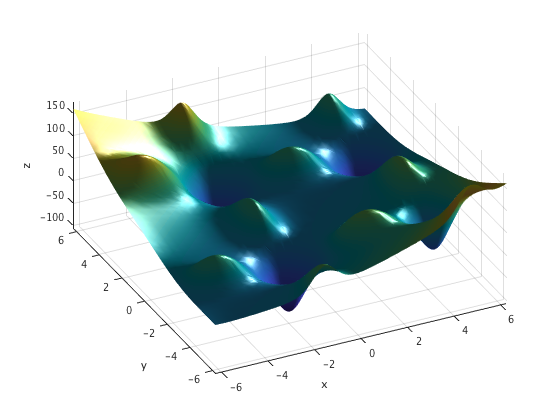

clf
f1 = @(x, y) sin(x).*exp((1 - cos(y)).^2) + cos(y).*exp((1 - sin(x)).^2) +...
    (x - y).^2;
fsurf(f1, [-2*pi 2*pi], 'LineStyle', 'none');
shading interp
light;
view(-26, 52)
material metal
xlabel('x'), ylabel('y'), zlabel('z')

Parametrized surface. The functions must be vectorized.

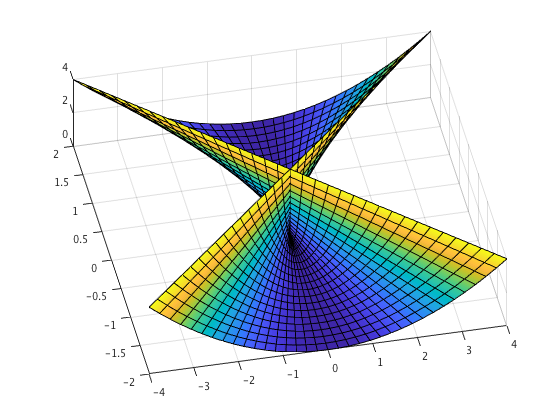

fsurf(@(u,v)u.*v, @(u,v)u, @(u,v)v.^2, [-2 2 -2 2])
view([-12, 74])

It is easy to visualize the complex function $sin(x + iy)$ with f`surf`. Here's the real part.

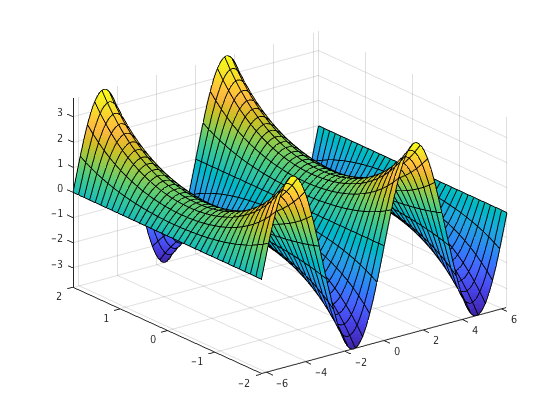

fsurf(@(x,y) real(sin(x + 1i*y)), [-2*pi 2*pi, -2 2])

The imaginary part.

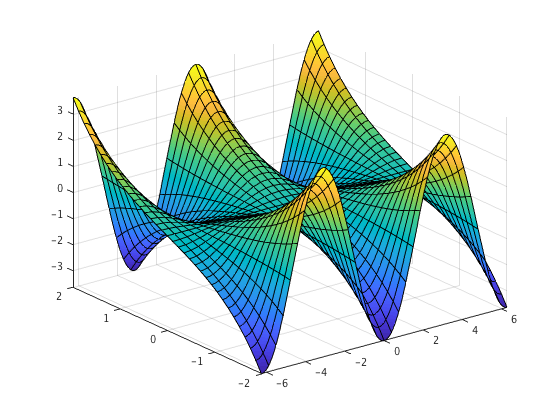

fsurf(@(x,y) imag(sin(x + 1i*y)), [-2*pi 2*pi, -2 2])

The absolute value.

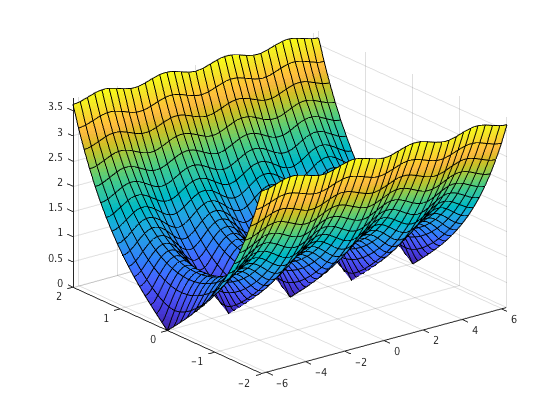

fsurf(@(x,y) abs(sin(x + 1i*y)), [-2*pi 2*pi, -2 2])

The phase angle. `fsurf` tries to filter singularities and discontinuities. This looks better than

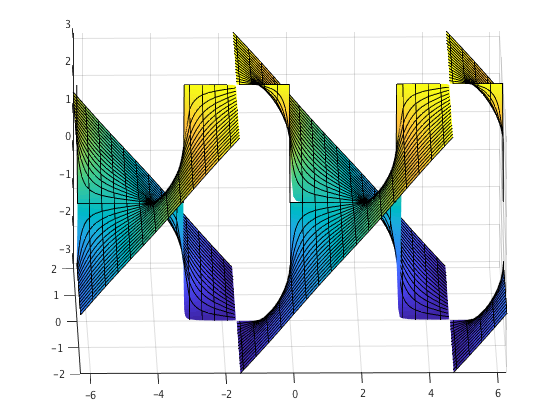

fsurf(@(x,y) angle(sin(x + 1i*y)), [-2*pi 2*pi, -2 2])
view(-1, 24)

this

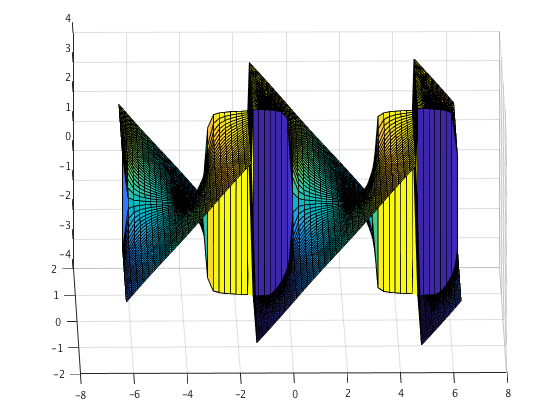

[XX, YY] = meshgrid(linspace(-2*pi, 2*pi, 60), linspace(-2, 2, 60));
ZZ = angle(sin(XX + 1i*YY));
surf(XX, YY, ZZ)
view(-1, 24)

## fimplicit3

We can plot surfaces given implicitly with the command `fimplicit3`.

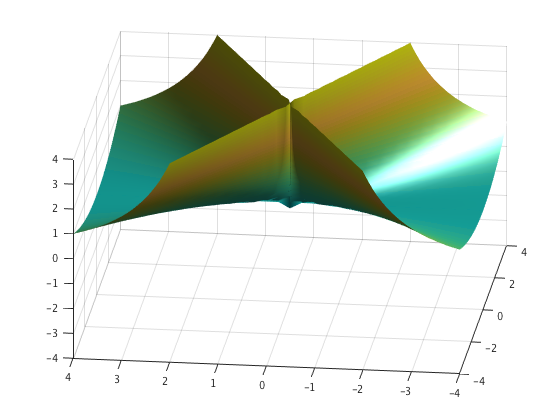

fimplicit3(@(x, y, z) x.^2 - y.^2 .* z, [-4 4], 'EdgeColor','none')
shading interp
camlight
view([-83 33])

## Contour plots

A contour plot of the surface used earlier.

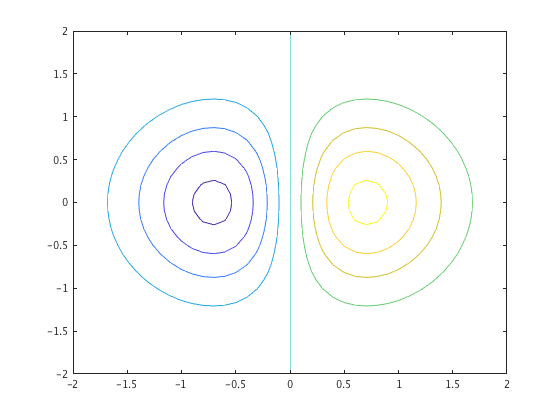

[X, Y] = meshgrid(-2:0.1:2);
Z = X.*exp(-X.^2 - Y.^2);
contour(X, Y, Z);

Contour plot with 6 levels.

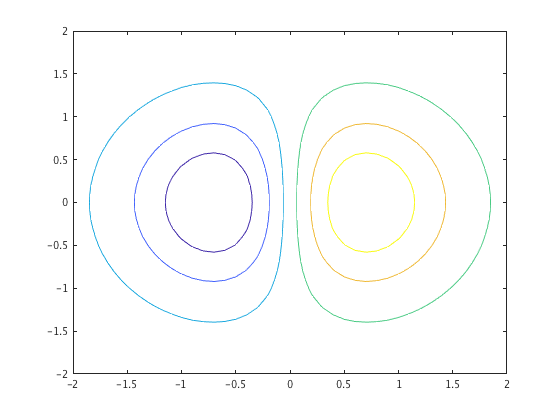

contour(X, Y, Z, 6);

Contour plot with levels 0.1, 0.2, and 0.3

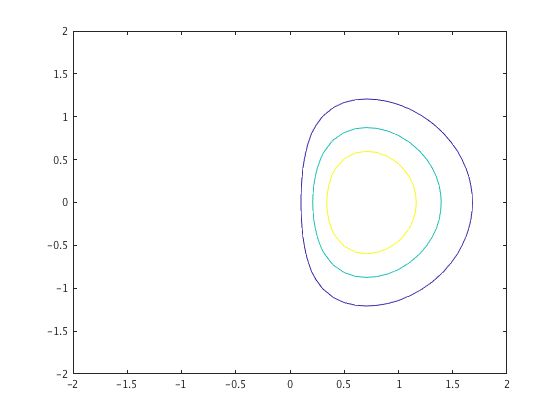

contour(X, Y, Z, [0.1 0.2 0.3]);

Contour plot with a single level -0.1. The level must be given as a two element vector and not a scalar.

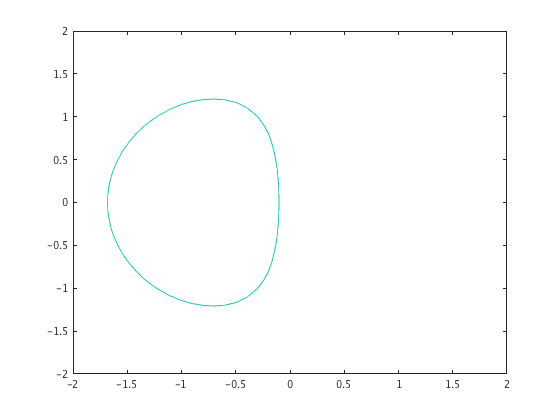

contour(X, Y, Z, [-0.1 -0.1]);

We can also give line specifications.

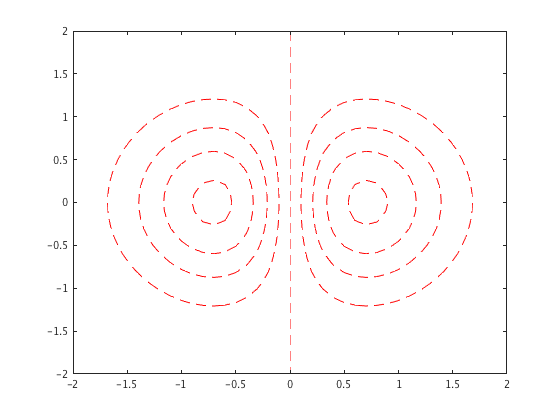

contour(X, Y, Z, 'Color', 'r', 'LineStyle', '--');

The contours can also be labeled.

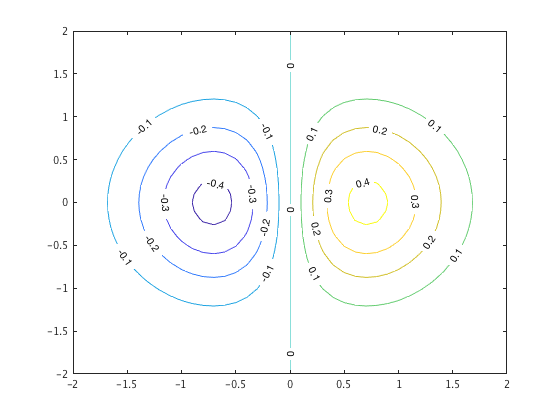

contour(X, Y, Z, 'ShowText', 'on');

The command `contourf` makes a filled contour plot.

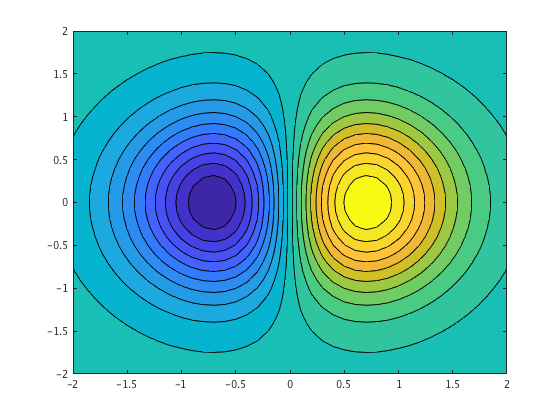

contourf(X, Y, Z, 20);

A filled contour plot with labels.

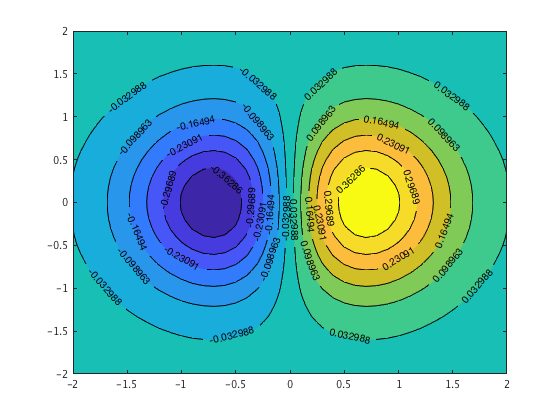

contourf(X, Y, Z, 12, 'ShowText', 'on');

The command `contour3` plots the contours at the right Z-heights. Tilde ~ as an output argument tells MATLAB to ignore the return value. 

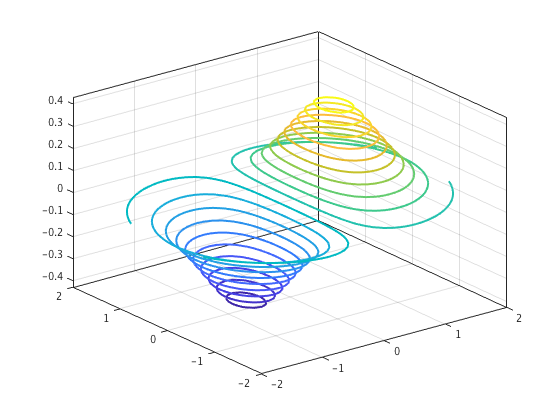

[~, h] = contour3(X, Y, Z, 20);
set(h, 'LineWidth', 2)

The command `fcontour` is an easy to use contour plotter.

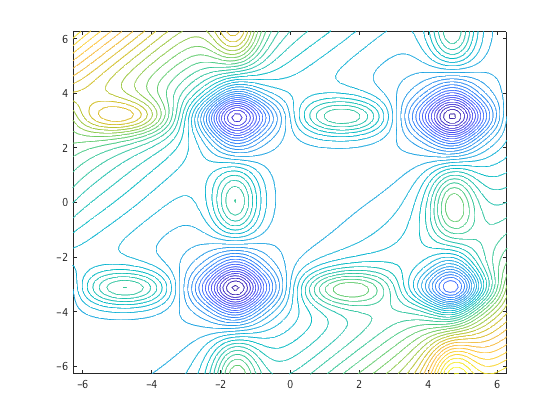

fcontour(f1, [-2*pi 2*pi], 'MeshDensity', 100, 'LevelStep', 7)

Filled version.

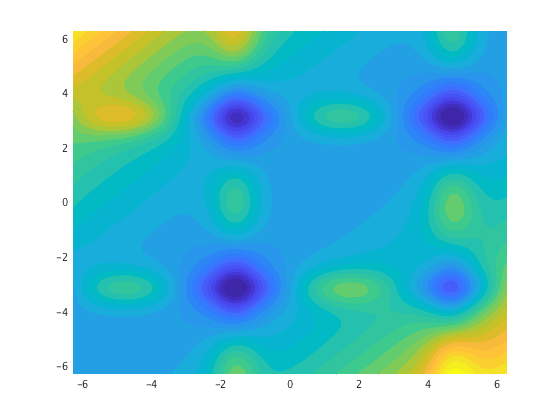

fcontour(f1, [-2*pi 2*pi], 'LevelStep', 10, 'Fill', 'on')

## Nonuniformly spaced data

The previous plots were made with uniformly spaced data. With nonuniformly spaced data we can do as follows.

Make some nonuniformly spaced test data.

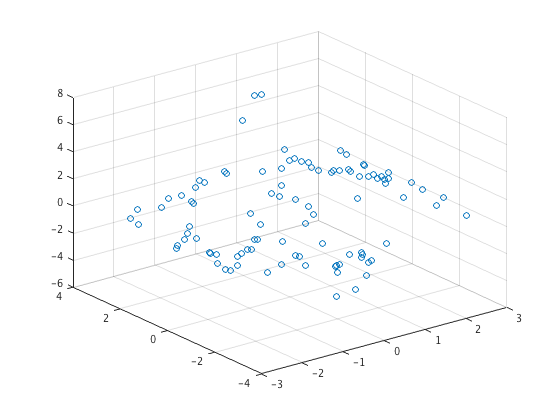

clf
x = rand(100,1)*6 - 3;
y = rand(100,1)*6 - 3;
z = peaks(x,y);
scatter3(x, y, z)

Create a uniformly spaced grid for plotting.

nn = 30;
xx = linspace(min(x), max(x), nn);
yy = linspace(min(y), max(y), nn);
[X, Y] = meshgrid(xx, yy);

Now create a scatteredInterpolant object to interpolate the nonuniform data.

f = scatteredInterpolant(x, y, z)

f =   scatteredInterpolant with properties:

                 Points: [100×2 double]
                 Values: [100×1 double]
                 Method: 'linear'
    ExtrapolationMethod: 'linear'


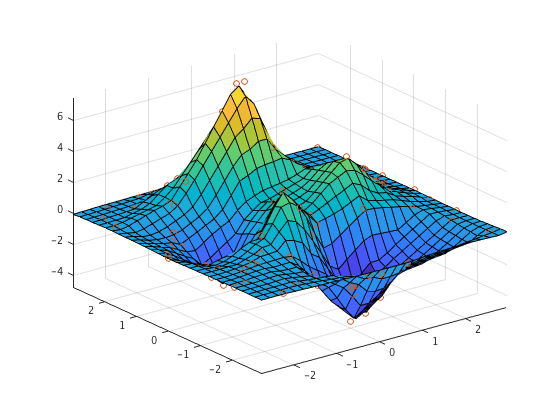

Z = f(X, Y);
surf(X,Y,Z)
axis tight, hold on
plot3(x, y, z, 'o')

Set the surface partially transparent.

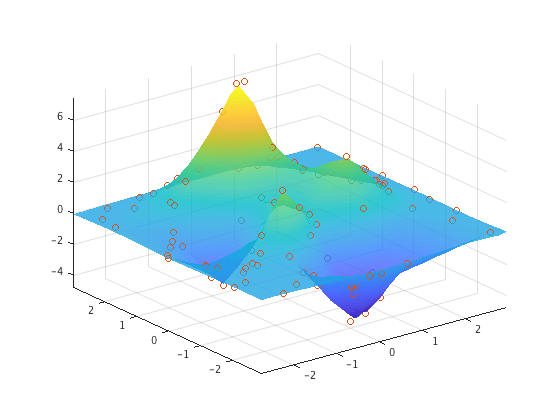

shading interp
alpha(0.8)